% Finite temperature TFIM analytics

% Energy expectation via ED
J = 1;
Gm = 0.5;
h = 0;
N = 10;
bc = 'PBC';

H = hIM(J, Gm, h, N, bc);
nt = 20; % number of temperatures
T_ = linspace(0.01, 1, nt); % temperature

e = zeros(1, nt);
for i = 1:nt
    Z = trace(expm(-H/T_(i))); % partition function
    E = trace(expm(-H/T_(i)) * H)/Z;
    e(i) = E/N;
end


% analytical calculations

% fermionic correlation functions
eps = @(p) sqrt(1+(Gm/J)^2+2*(Gm/J)*cos(kspace(N, p)));
f = @(j, l, p) sum(1/N*exp(1i*(l-j)*kspace(N, p)).*(1-((Gm/J)-cos(kspace(N, p)))./eps(p))/2);
g = @(j, l, p) sum(1/N*exp(-1i*(l-j)*kspace(N, p)).*(Gm/J*sin(kspace(N, p)))/2);
M = zeros(N, N, 2); % accounting for different parities
for j = 1:N
    for l = 1:N
        M(j, l, 1) = isequal(j, l) - 2*(conj(f(l, j, 0)) + g(j, l, 0));
        M(j, l, 2) = isequal(j, l) - 2*(conj(f(l, j, 1)) + g(j, l, 1));
    end
end
eta = [det(M(:,:,1)), det(M(:,:,2))];
eta = [1, 1];
Z = @(b) 1/2*exp(b*sum(eps(0))) * (prod(1+exp(-2*b*eps(0))) + eta(1)*prod(1-exp(-2*b*eps(0)))) + 1/2*exp(b*sum(eps(1))) * (prod(1+exp(-2*b*eps(1))) + eta(2)*prod(1-exp(-2*b*eps(1))));
Z1 = @(b) trace(expm(-b*H));



take_exp = @(p, b, mu) Esp(p, b, mu, eps, Z, [det(M(:,:,1)), det(M(:,:,2))]);
energy_expectation = 0;
b = T_.^(-1);
b = 2;
for p = [0, 1]
    E = eps(p);
    for mu = 1:N
        energy_expectation = energy_expectation + take_exp(p, b, mu) * E(mu);
    end
end
energy_expectation

energy_expectation = 3.9912e-09 + 3.6690e-27i

take_exp(1,2,1)

ans = 1.7789e-10 + 3.6254e-28i

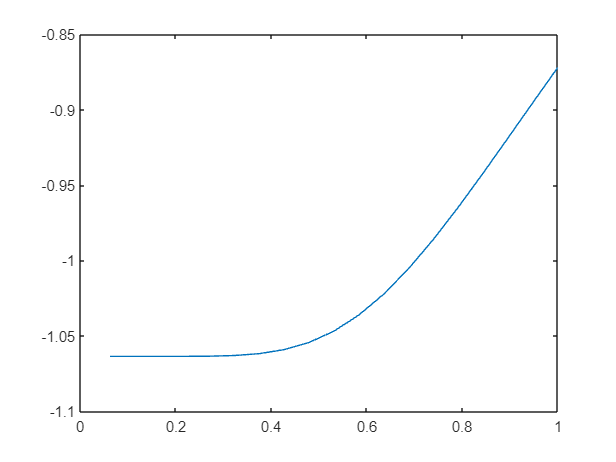



plot(T_, e)



det(M(:,:,1))

ans = 0.0062

eps(0)

ans =     0.5468    0.8138    1.1180    1.3556    1.4836    1.4836    1.3556    1.1180    0.8138    0.5468


function kk = kspace(N, p)
% create the correct k space based on the parity of sites and parity of
% sectors
    switch mod(N, 2)
        case 0
            switch p
                case 0
                    % even number of spins, positive parity subspace
                    kk = -(N-1)*pi/N:2*pi/N:(N-1)*pi/N;
                case 1
                    % even number of spins, negative parity subspace
                    kk = -(N-2)*pi/N:2*pi/N:pi;
            end
        case 1
            switch p
                case 0
                    % odd number of spins, positive parity subspace
                    kk = -(N-2)*pi/N:2*pi/N:pi;
                case 1
                    % odd number of spins, negative parity subspace
                    kk = -(N-1)*pi/N:2*pi/N:(N-1)*pi/N;
            end
    end
end

function val = Esp(p, b, mu, eps, Z, eta)
% Compute the energy expectation value based on partition function Z and
% parities eta
    E = eps(p);
    e = E(mu);
    % val = exp(-2*b*e)/2 * (prod_except(1+exp(-2*b*E), mu) - eta(p+1)*prod_except(1-exp(-2*b*E), mu));
    val = 1/2 * (prod_except(1+exp(-2*b*E), mu) + eta(p+1)*prod_except(1-exp(-2*b*E), mu));
    val = val/Z(b);
end

function val = prod_except(A, i)
    A(i) = [];
    val = prod(A);
end





